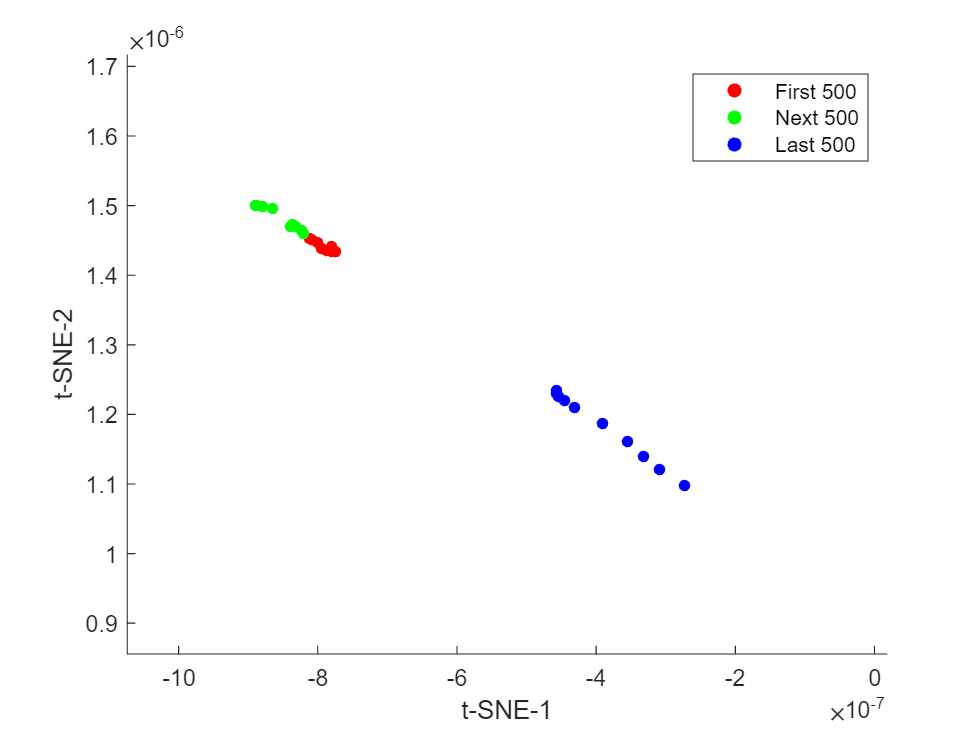

points = analysisstruct.zValues;            % N×2 (or N×3) matrix

% Indices for the first and last 20 rows
begin_idx = 1:10;
second_idx = 11:20;
end_idx   = size(points,1)-9 : size(points,1);

figure
hold on
scatter(points(begin_idx,1), points(begin_idx,2), 24, 'r', 'filled')   % first 20 in red
scatter(points(second_idx, 1), points(second_idx, 2), 24, 'green', 'filled')
scatter(points(end_idx,  1), points(end_idx,  2), 24, 'b', 'filled')   % last 20 in blue
legend({'First 500','Next 500','Last 500'})
xlabel('t-SNE-1'); ylabel('t-SNE-2')
axis equal
hold off

mat = load('_test_folder/34A_f0t1000r0.mat');

head_data = mat.pred(:, :, 1:3);
the_size = size(head_data)

the_size =         1000           3           3


reshaped_head_data = reshape(head_data, the_size(1), the_size(2)*the_size(3))

reshaped_head_data =   142.4663   98.5060   25.4784  141.0143   72.6089   24.4486  159.7295   84.5150    5.0106
  151.2358  100.2936   25.5218  144.7805   69.2837   24.4110  162.9763   81.7916    5.1599
  155.8675   97.9134   26.3198  143.9630   75.0149   23.6627  166.6938   79.9503    4.7051
  159.6080   95.4375   27.5181  145.7699   76.1041   25.8699  170.2314   79.7873    4.7656
  162.7374   92.9241   26.9166  151.0485   72.7629   25.7757  172.7289   75.6114    6.2665
  165.8334   91.2692   27.2784  151.9188   72.9108   26.6337  176.3789   72.6795    6.4149
  168.5903   88.9634   27.7972  154.4175   69.6522   26.8628  178.9946   70.0526    6.5384
  171.4765   86.4169   27.4812  158.8420   65.4170   26.4478  182.5875   67.6428    6.2588
  175.3762   84.1977   25.8476  163.0797   60.4941   24.3591  186.6939   64.8082    6.1770
  178.8156   82.0502   25.2658  168.1538   59.7003   24.5378  192.3156   62.2801    6.4120



d = tsne(reshaped_head_data)

d =    15.4884  -14.3892
   15.6907  -14.4481
   15.8074  -14.4747
   15.9435  -14.5228
   16.1964  -14.6076
   16.4205  -14.6738
   16.6554  -14.7373
   17.0191  -14.8393
   17.4967  -14.8805
   17.8981  -14.8590


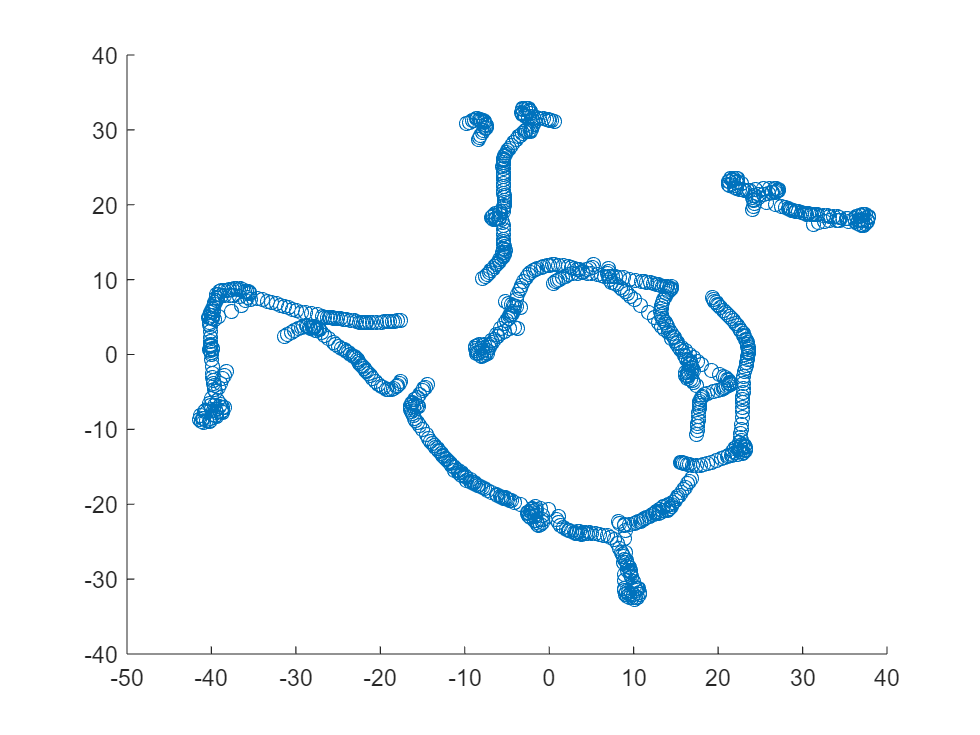


scatter(d(:, 1), d(:, 2))

mat = load('_test_folder/34A_f0t1000r0.mat');

head_data = mat.pred(:, :, :);
the_size = size(head_data)

the_size =         1000           3          23


reshaped_head_data = reshape(head_data, the_size(1), the_size(2)*the_size(3))

reshaped_head_data =   142.4663   98.5060   25.4784  141.0143   72.6089   24.4486  159.7295   84.5150    5.0106  139.6403   91.5798   17.5890  122.9833   73.4785   19.5445  122.3435   78.8744   10.0397   92.8703   60.6198   18.4381  143.8434   90.4326   -2.3628  140.8829   89.3188   -2.1222  133.4859   90.7499    5.3738  133.7858   91.3920   13.1163  143.6712   83.4419   -2.2980  141.4568   82.2940   -1.9867  136.4215   74.9996    6.6536  138.4934   80.1878   15.7399  115.1145   84.8065   -1.7025  135.2095   86.9111
  151.2358  100.2936   25.5218  144.7805   69.2837   24.4110  162.9763   81.7916    5.1599  142.7612   88.4525   18.6742  126.9740   72.7308   20.1036  130.9471   82.7011    8.4484   96.8451   59.9910   22.7179  144.7016   88.3587   -2.2700  140.7703   88.8200   -2.0833  134.8578   90.5296    6.3476  136.1441   90.1469   13.5166  144.5906   80.0730   -1.7477  141.4601   73.1071   -0.3782  139.0742   71.5130    7.5371  141.5058   78.1848   16.2542  112.9939   83.5598    0.89


d = tsne(reshaped_head_data)

d =     1.6058  -20.5586
    1.6017  -20.6163
    1.5960  -20.6663
    1.5850  -20.8206
    1.5698  -21.0185
    1.5475  -21.2240
    1.5291  -21.4833
    1.4847  -21.7974
    1.4489  -22.0824
    1.4449  -22.1511


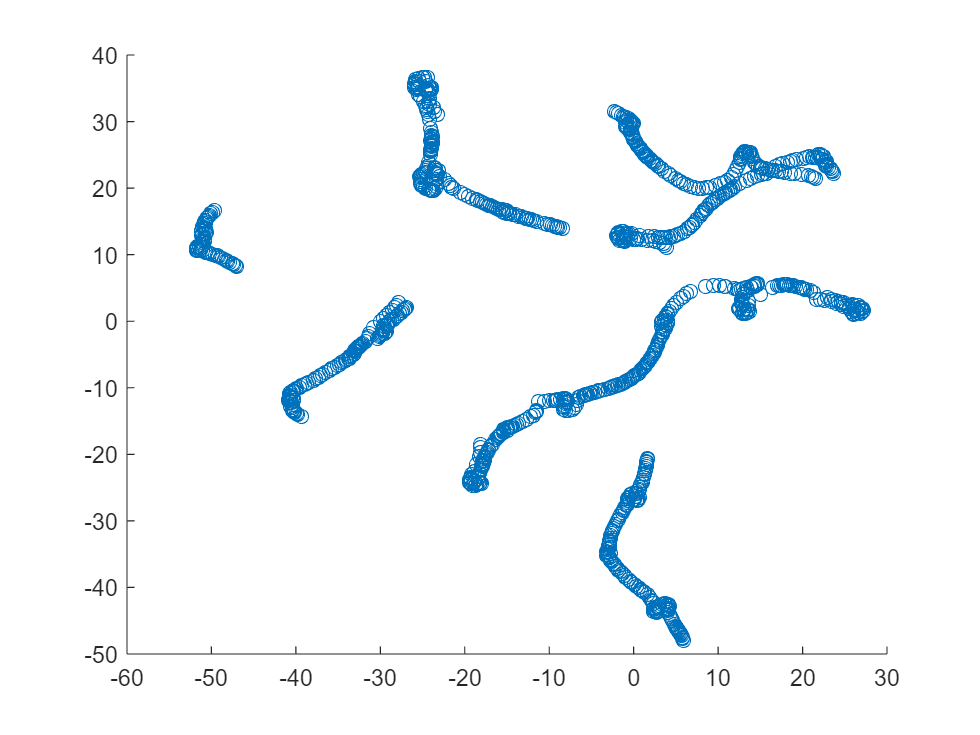


scatter(d(:, 1), d(:, 2))

% function viz_tsne_plot(analysisstruct)
%VIZ_TSNE_PLOT Summary of this function goes here
%Detailed explanation goes herez
zValue = analysisstruct.zValues;

Unable to resolve the name 'analysisstruct.zValues'.


the_size = size(zValue);
middle = round(the_size / 2);

former = zValue(1:middle, :);
later = zValue(middle:end, :);

scatter(former(:, 1), former(:, 2), "red")
% hold on;
% scatter(later(:, 1), later(:, 2), "green")
% end